# Rotation matrix: 2D Example 3 bis

A=rotx(pi/6)*roty(pi/2)

A =          0         0    1.0000
    0.5000    0.8660         0
   -0.8660    0.5000         0


B=rotx(-pi/12)

B =     1.0000         0         0
         0    0.9659    0.2588
         0   -0.2588    0.9659


R_B_A=A'*B

R_B_A =          0    0.7071   -0.7071
         0    0.7071    0.7071
    1.0000         0         0


## Plotting

FA=eye(3)

FA =      1     0     0
     0     1     0
     0     0     1


FB=eye(3)

FB =      1     0     0
     0     1     0
     0     0     1


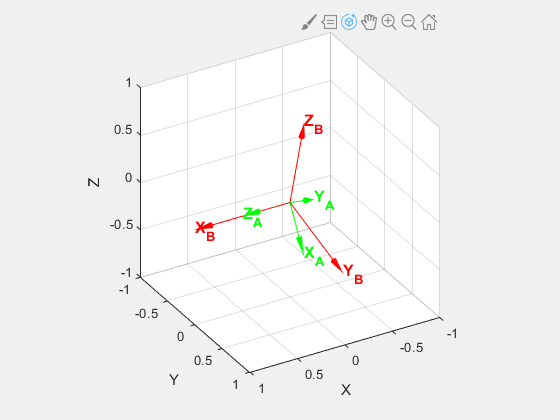


H1=trplot(FA, ... % Build frame FA with all the options
    'frame', 'A', ...
    'color', 'g',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'length',0.5,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(A, H1,'handle',H1) % Plot FB with the given orientation. H1 is a 'handler'

hold on

H2=trplot(FB, ... % Build frame FB with all the options
    'frame', 'B', ...
    'color', 'r',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'length',1,...
    'arrow',...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[150,30],...
    'width', 1.2);
trplot(B, H2,'handle',H2) % Plot FB with the given orientation. H1 is a 'handler'

# Mapping


$$\[{}^AP = {}_B^AR{}^BP\]$$


% R_B_A=[0.6124 -0.5 -0.6124;...
%        0.3536 0.866 -0.3536;...
%        0.7071 0 0.7071]
R_B_A=rotx(pi/6)*rotz(pi/3)

R_B_A =     0.5000   -0.8660         0
    0.7500    0.4330   -0.5000
    0.4330    0.2500    0.8660


P_B=[1.67 0.36 -0.25]'

P_B =     1.6700
    0.3600
   -0.2500


P_A=R_B_A*P_B

P_A =     0.5232
    1.5334
    0.5966


# Homogeneous Transform: example

T_B_A=[1 0 0 0;...
       0 0 -1 3;...
       0 1 0 1;...
       0 0 0 1]

T_B_A =      1     0     0     0
     0     0    -1     3
     0     1     0     1
     0     0     0     1


   P_B=[0 1 1 1]'

P_B =      0
     1
     1
     1


P_A=T_B_A*P_B

# General Operators: Example

## Vertices/vectors

Vertices=[0 0.4 0.4 0 0 0.4 0.4 0;...
           0 0 0.4 0.4 0 0 0.4 0.4;...
           0 0 0 0 0.4 0.4 0.4 0.4;...
           1 1 1 1 1 1 1 1]

P_A =      0
     2
     2
     1


Vertices =          0    0.4000    0.4000         0         0    0.4000    0.4000         0
         0         0    0.4000    0.4000         0         0    0.4000    0.4000
         0         0         0         0    0.4000    0.4000    0.4000    0.4000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


## Operator

T_B_A=Operator(30*pi/180, 0.3,0.4,0.6)

T_b_a =     0.8660   -0.5000         0    0.3000
    0.5000    0.8660         0    0.4000
         0         0    1.0000    0.6000
         0         0         0    1.0000


T_B_A =     0.8660   -0.5000         0    0.3000
    0.5000    0.8660         0    0.4000
         0         0    1.0000    0.6000
         0         0         0    1.0000


T_B_A_RTB=transl(0.3,0.4,0.6)*trotz(30*pi/180)

## Symbolic Operator

syms alpha tx ty tz
Operator_H=Operator(alpha, tx,ty,tz)
Operator_RTB=transl(tx,ty,tz)*trotz(alpha)

## Vertices

New_vertices=Operator(30*pi/180, 0.3,0.4,0.6)*Vertices

T_B_A_RTB =     0.8660   -0.5000         0    0.3000
    0.5000    0.8660         0    0.4000
         0         0    1.0000    0.6000
         0         0         0    1.0000


$$T\_b\_a = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & \mathrm{tx}\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & \mathrm{ty}\\ 0 & 0 & 1 & \mathrm{tz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Operator\_H = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & \mathrm{tx}\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & \mathrm{ty}\\ 0 & 0 & 1 & \mathrm{tz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$Operator\_RTB = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & \mathrm{tx}\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & \mathrm{ty}\\ 0 & 0 & 1 & \mathrm{tz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_b_a =     0.8660   -0.5000         0    0.3000
    0.5000    0.8660         0    0.4000
         0         0    1.0000    0.6000
         0         0         0    1.0000


New_vertices =     0.3000    0.6464    0.4464    0.1000    0.3000    0.6464    0.4464    0.1000
    0.4000    0.6000    0.9464    0.7464    0.4000    0.6000    0.9464    0.7464
    0.6000    0.6000    0.6000    0.6000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


# Inverse transform

syms alpha x y
T_A_B=trotz(-alpha)*transl(-x,-y,0)

$$T\_A\_B = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & -x\,\cos\left(\alpha \right)-y\,\sin\left(\alpha \right)\\ -\sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & x\,\sin\left(\alpha \right)-y\,\cos\left(\alpha \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Operator/Functions

function T_b_a = Operator(alpha, tx,ty,tz)
           T_b_a=[cos(alpha) -sin(alpha) 0 tx;...
                  sin(alpha)  cos(alpha) 0 ty;...
                  0 0 1 tz;...
                  0 0 0 1] 
end